load("AllSolvedData100000.mat", 'AllSolvedData')
head(AllSolvedData)

          Var1              Var2    
    ________________    ____________

    1×1 occupancyMap    {6×3 double}
    1×1 occupancyMap    {5×3 double}
    1×1 occupancyMap    {7×3 double}
    1×1 occupancyMap    {4×3 double}
    1×1 occupancyMap    {3×3 double}
    1×1 occupancyMap    {6×3 double}
    1×1 occupancyMap    {6×3 double}
    1×1 occupancyMap    {4×3 double}



Database = AllSolvedData;
statespace = stateSpaceSE2;
statespace.StateBounds = [[0 20]; [0 20]; [-3.1416 3.1416]];


mpnet = mpnetSE2;
mpnet.LossWeights = [100 100 0];
mpnet.EncodingSize = [9 9];

split = 0.8;
trainData = Database(1:int16(0.8*end),:);
validationData = Database(int16(0.8*end)+1:end,:);

dsTrain = mpnetPrepareData(trainData,mpnet);
dsValidation = mpnetPrepareData(validationData,mpnet);

preparedDataSample = read(dsValidation);
preparedDataSample(1,:)

ans = 1×2 cell array
    {[0.5700 0.5550 1 0.5000 0.5155 0.5586 0.7765 0.0834 0.2809 0.3378 0.3378 0.3378 0.3378 0.3378 0.3378 0.2240 0.3378 0.2809 0.2809 0.3378 0.3378 0.5153 0.6595 0.6595 0.4987 0.2573 0.4987 0.3378 0 0.0160 0.1769 0.4987 0.7089 0.6595 0.4987 0.2573 0.4987 0.3378 0 0.0160 0.1769 0.4987 0.5248 0.3378 0.3378 0.2976 0.5153 0.3378 0.2809 0.3378 0.3378 0.5248 0.4987 0.2171 0.1769 0.3378 0.5791 0.3378 0.3378 0.6193 0.6595 0.7332 0.6079 0.4987 0.4987 0.5248 0.6219 0.3378 0.3378 0.6595 0.9411 1 0.8226 0.6079 0.4987 0.4987 0.5650 0.3378 0.3378 0.6595 0.9411 0.9813 0.8204 0.4987 0.2171 0.2171 0.4987 0.3378 0.3378 0.6193 0.6595 0.6595 0.6595 0.4987 0.1769 0.1769 0.4987 0.3378 0.2809 0.3378 0.3378 0.3378 0.3378 0.3378 0.1507 0.1507 0.3378 0.2809]}    {[0.5602 0.5530 0.9865 0.3846]}


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:05        0.001                            118.47
            1        1       00:00:05        0.001          119.47                  
           50       17       00:00:16        0.001          1.1524                  
          100       34       00:00:20        0.001         0.62755                  
          150       50       00:00:23        0.001         0.41467           0.39921
Training stopped: Max epochs completed


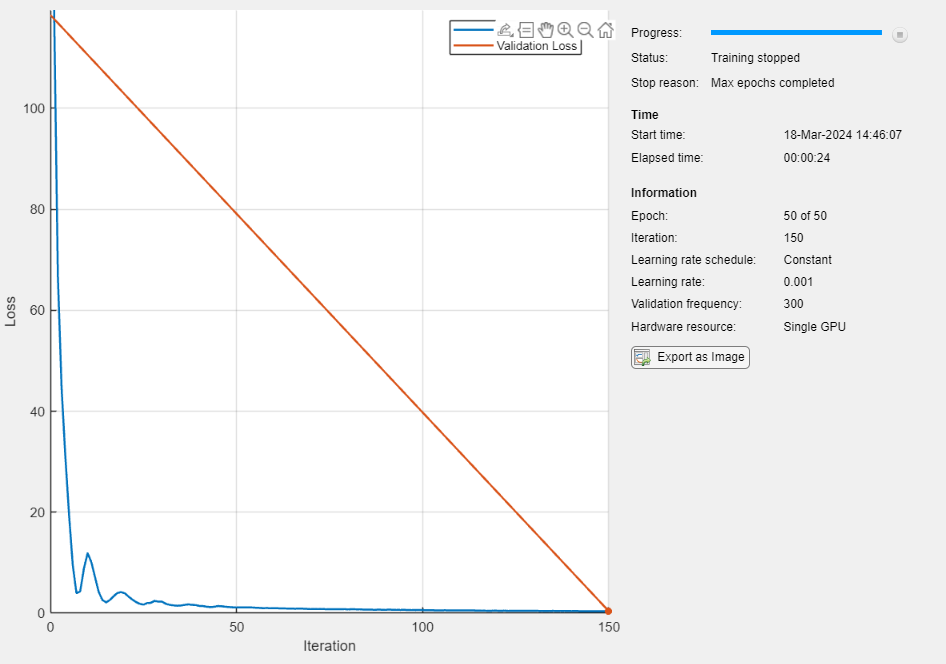

options = trainingOptions("adam",...
        MiniBatchSize=2048,...
        MaxEpochs=50,...
        Shuffle="every-epoch",...
        ValidationData=dsValidation,...
        ValidationFrequency=300,...
        Plots="training-progress");

    % Train network
[net, info] = trainnet(dsTrain, mpnet.Network, @mpnet.loss, options);

    
    % Update Network property of mpnet object with net
mpnet.Network = net;


mpnet

mpnet =   mpnetSE2 with properties:

     StateBounds: [3×2 double]
     LossWeights: [100 100 0]
    EncodingSize: [10 10]
       NumInputs: 108
      NumOutputs: 4
         Network: [1×1 dlnetwork]


save("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\DL\mpnet.mat", "mpnet")



stateSamplerDL = stateSamplerMPNET(statespace,mpnet);

ind = randi(height(validationData));
map = validationData(ind,:).Var1;
start = double(validationData(ind,:).Var2{1,:}(1,:));
goal = double(validationData(ind,:).Var2{1,:}(end,:));


stateSamplerDL.Environment = map;
stateSamplerDL.StartState = start;
stateSamplerDL.GoalState = goal;
stateSamplerDL

stateSamplerDL =   stateSamplerMPNET with properties:

               StateSpace: [1×1 stateSpaceSE2]
    MotionPlanningNetwork: [1×1 mpnetSE2]
              Environment: [1×1 occupancyMap]
               StartState: [8 13 0]
                GoalState: [15.8448 3.9318 0.9176]
        MaxLearnedSamples: 50
            GoalThreshold: 1


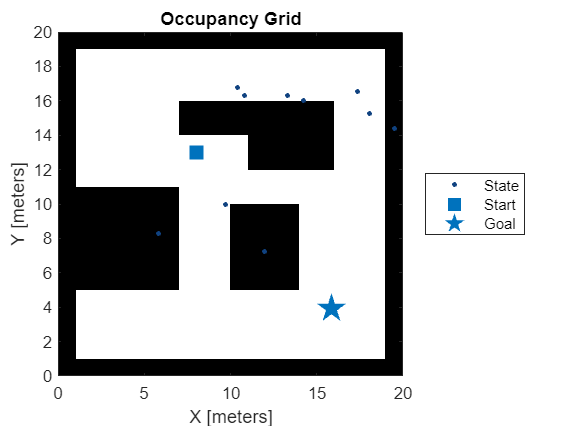

numSamples =30;
stateSamplerDL.MaxLearnedSamples = 30;
samples = sample(stateSamplerDL, numSamples);
figure
show(map);
hold on;
plot(samples(:,1),samples(:,2),plannerLineSpec.state{:})
plot(start(1),start(2),plannerLineSpec.start{:});
plot(goal(1),goal(2),plannerLineSpec.goal{:});
legend(Location="eastoutside")

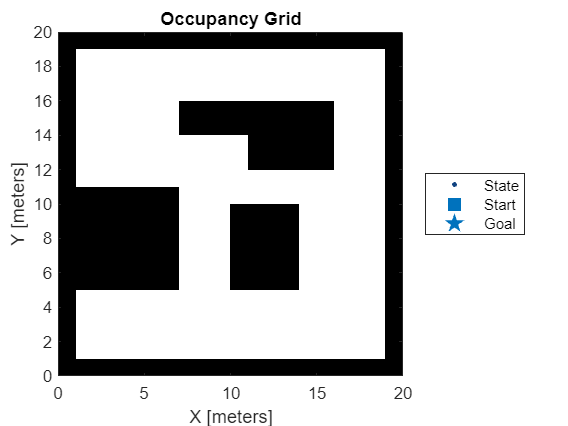

stateValidator = validatorOccupancyMap(statespace,Map=map);
stateValidator.ValidationDistance = 0.1;
show(map)

stateValidator

stateValidator =   validatorOccupancyMap with properties:

                   Map: [1×1 occupancyMap]
            StateSpace: [1×1 stateSpaceSE2]
             XYIndices: [1 2]
    ValidationDistance: 0.1000


start

start =      8    13     0


goal

goal =    15.8448    3.9318    0.9176


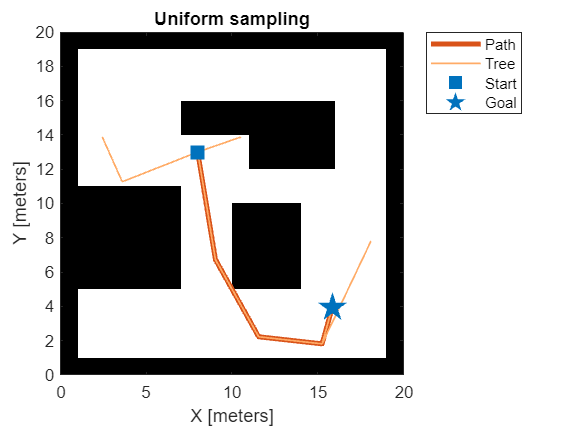


% Create RRT* planner with default uniform sampler
plannerUniformSampling = plannerRRTStar(statespace,stateValidator,MaxConnectionDistance=10,StateSampler=stateSamplerUniform(statespace));
[pathUniformSampling,solutionInfoUniformSampling] = plan(plannerUniformSampling,start,goal);

% Visualize results for uniform sampling
figure
show(map)
hold on;
plot(pathUniformSampling.States(:,1),pathUniformSampling.States(:,2),plannerLineSpec.path{:})
plot(solutionInfoUniformSampling.TreeData(:,1),solutionInfoUniformSampling.TreeData(:,2),plannerLineSpec.tree{:})
plot(start(1),start(2),plannerLineSpec.start{:});
plot(goal(1),goal(2),plannerLineSpec.goal{:});
legend(Location="northeastoutside")
title("Uniform sampling")

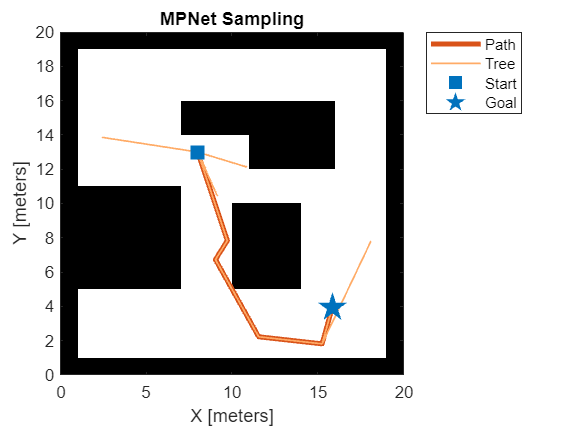

plannerDLSampling = plannerRRTStar(statespace,stateValidator,MaxConnectionDistance=10,StateSampler=stateSamplerDL);
[pathDLSampling,solutionInfoDLSampling] = plan(plannerDLSampling,start,goal);

% Visualize results with deep learning based sampling
figure
show(map);
hold on;
plot(pathDLSampling.States(:,1),pathDLSampling.States(:,2),plannerLineSpec.path{:})
plot(solutionInfoDLSampling.TreeData(:,1),solutionInfoDLSampling.TreeData(:,2),plannerLineSpec.tree{:})
plot(start(1),start(2),plannerLineSpec.start{:})
plot(goal(1),goal(2),plannerLineSpec.goal{:})
legend(Location="northeastoutside")
title("MPNet Sampling")


pathDLSampling.States

ans =     8.0000   13.0000         0
    9.7281    7.8344   -2.4265
    9.0349    6.7312   -0.0074
   11.5556    2.2296   -1.2570
   15.2540    1.8163   -3.1045
   15.8448    3.9318    0.9176


% Number of runs to benchmark the planner
runCount = 30;

% Create plannerBenchmark object
pb = plannerBenchmark(stateValidator,start,goal);

% Create function handles to create planners for uniform sampling and deep
% learning-based sampling
plannerUniformSamplingFcn = @(stateValidator)plannerRRTStar(stateValidator.StateSpace,stateValidator,MaxConnectionDistance=10);
plannerMPNetSamplingFcn = @(stateValidator)plannerRRTStar(stateValidator.StateSpace,stateValidator,MaxConnectionDistance=10,StateSampler=stateSamplerDL);

% Create plan function
plnFcn = @(initOut,s,g)plan(initOut,s,g);

% Added both planners to plannerBenchmark object
addPlanner(pb,plnFcn,plannerUniformSamplingFcn,PlannerName="Uniform");
addPlanner(pb,plnFcn,plannerMPNetSamplingFcn,PlannerName="MPNet");

% Run planners for specified runCount
runPlanner(pb,runCount)

Initializing Uniform ...
Done.
Planning a path from the start pose (8 13 0) to the goal pose (15.8448 3.9318 0.91758) using Uniform.
Executing run 1.
Executing run 2.
Executing run 3.
Executing run 4.
Executing run 5.
Executing run 6.
Executing run 7.
Executing run 8.
Executing run 9.
Executing run 10.
Executing run 11.
Executing run 12.
Executing run 13.
Executing run 14.
Executing run 15.
Executing run 16.
Executing run 17.
Executing run 18.
Executing run 19.
Executing run 20.
Executing run 21.
Executing run 22.
Executing run 23.
Executing run 24.
Executing run 25.
Executing run 26.
Executing run 27.
Executing run 28.
Executing run 29.
Executing run 30.
Initializing MPNet ...
Done.
Planning a path from the start pose (8 13 0) to the goal pose (15.8448 3.9318 0.91758) using MPNet.
Executing run 1.
Executing run 2.
Executing run 3.
Executing run 4.
Executing run 5.
Executing run 6.
Executing run 7.
Executing run 8.
Executing run 9.
Executing run 10.
Executing run 11.
Executing run 12.


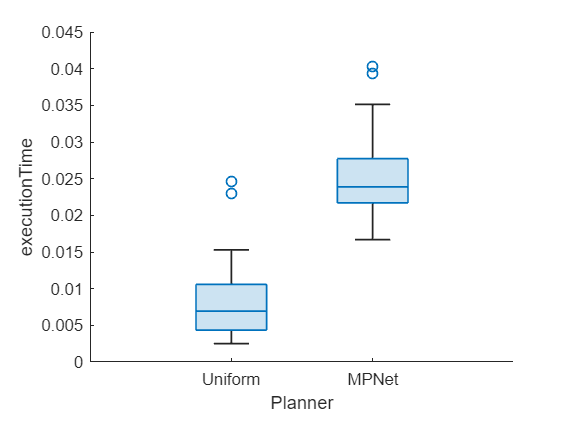

figure
show(pb,"executionTime")

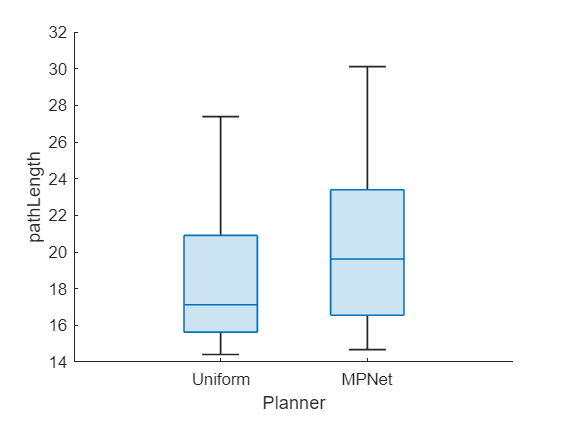

figure
show(pb,"pathLength")

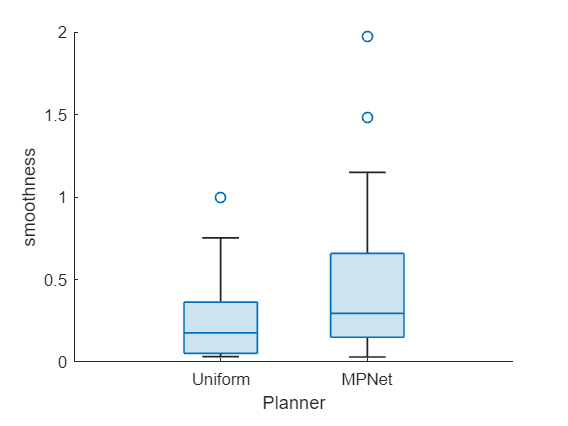

figure
show(pb,"smoothness")